clear all
close
clc

% Define the message signal
t = 0:0.01:10;
fm=2

fm = 2

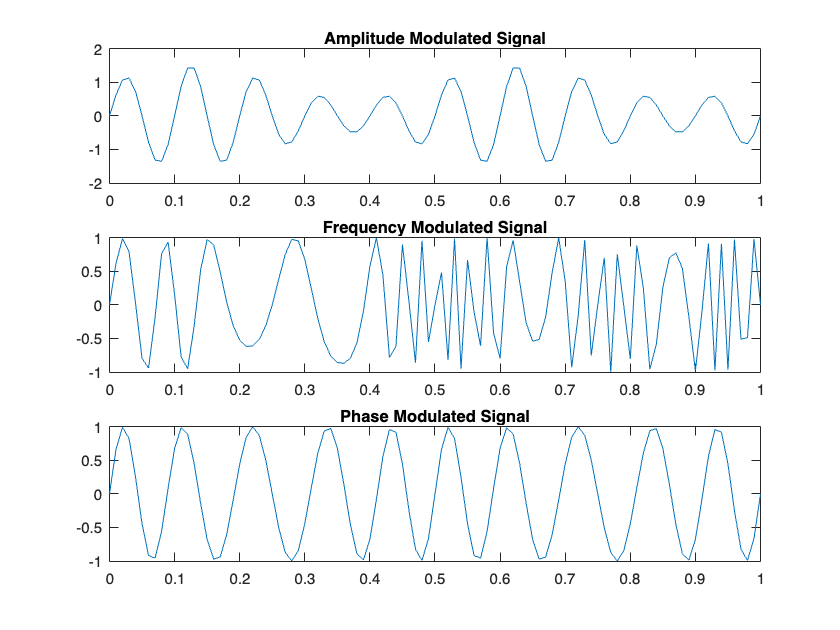

message = sin(2*pi*fm*t);

% Define the carrier signal
fc = 10; % carrier frequency
carrier = sin(2*pi*fc*t);

% Modulate the message signal with the carrier signal
am = (1 + 0.5.*message).*carrier;

% Modulate the message signal with the carrier signal
fm = sin(2*pi*(fc + 5.*message).*t);

% Modulate the message signal with the carrier signal
pm = sin(2*pi*fc*t + (pi/4).*message);

% Plot the original message signal, carrier signal, and modulated signal
% subplot(3,1,1)
% plot(t, message)
% title('Message Signal')
% 
% subplot(3,1,2)
% plot(t, carrier)
% title('Carrier Signal')

subplot(3,1,1)
plot(t, am)
title('Amplitude Modulated Signal')

subplot(3,1,2)
plot(t, fm)
title('Frequency Modulated Signal')

subplot(3,1,3)
plot(t, pm)
title('Phase Modulated Signal')